# Control design for inverted pendulum

clear all
close all

g = 9.8;
L = 1;
s = tf('s');

G = 1/(s^2-g/L); 

Plot the root locus of G:

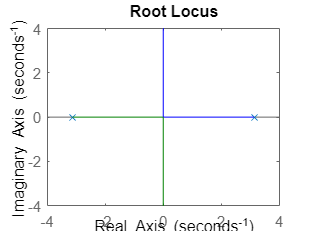

rlocus(G);

Even a large C=K will not bring the poles to the LHP. Therefore, we need to design a dynamic compensator, i.e., a controller with poles/zeros and gain.

## PD Controller Design

Let's try with a PD controller. The PD controller as introduced in class is given by


$$$$C(s) = k_p + k_ds = k_p \left( \frac{k_d}{k_p}s +1 \right) = k_p \left( \mu s +1 \right)$$$$


with


$$$$\mu = \frac{k_d}{k_p} .$$$$


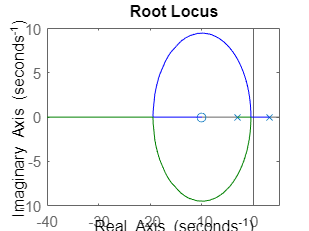

kp = 1; mu = 0.1;
C = kp*(mu*s+1);
rlocus(C*G);

 With a gain of 10.1, we will be able to place the closed loop poles at -0.5. Thus, we let

C = 10.1*C;

Now, we verify that the position of the closed loop poles is as desired

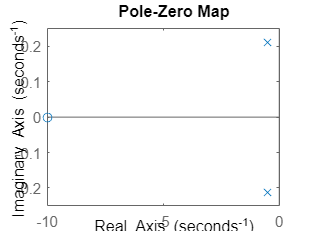

pzplot(minreal(C*G/(1+C*G)))

## PID Controller Design

Assume that the objective is to design a controller that ensures zero steady state error to step inputs. The previous controller will not be able to ensure this, since the system G is type zero, and the controller C will not add any pole at the origin. Let's verify by plotting the step response of the closed loop system:

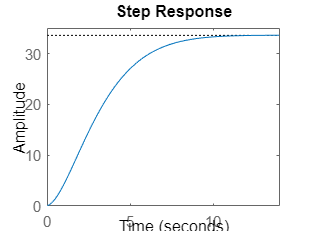

step(minreal(C*G/(1+C*G)))

As expected, there is a large steady state error. The final value (or the ) can also be computed as follows


$$\lim_{s \to 0} s \frac{1}{1+L(s)}\frac{1}{s} = \frac{1}{1+\frac{1}{-g/L} 10.1} = -32.68$$


To ensure zero steady state error to step input we need to increase the type of the system, i.e. we need to add an integrator. This is achieved by implementing a PID controller.

The PID controller is given by:


$$C(s)=k_p+k_ds+\frac{k_i}{s} = \frac{k_ds^2+k_ps +k_i}{s} = k_d \frac{(s^2+as + b)}{s}$$


with


$$a = \frac{k_p}{k_d} , \qquad b = \frac{k_i}{k_d} $$
 

Let's try to design a controller, for example:

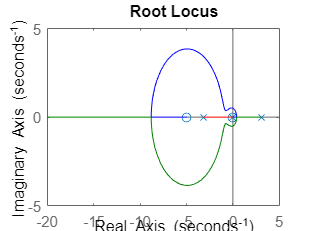

kp = 1; kd = 0.2; ki = 0.05;
C = kp+kd*s+ki/s;
rlocus(C*G);

From the root locus, we conclude that by adding a gain of 11.8, the poles of the close loop system will come to the LHP. 

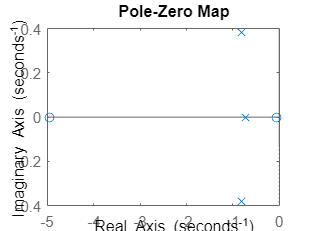

C = 11.8*C;
pzplot(minreal(C*G/(1+C*G)));

The step response of the system will now look like

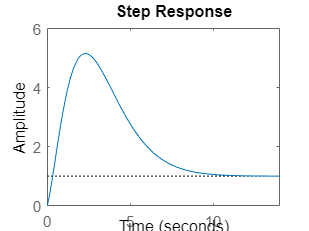

step(minreal(C*G/(1+C*G)));

demonstrating zero steady state error. 

C = C/(s/100+1);
[num den] = tfdata(C, 'v')

num = 1.0e+03 *

    0.2360    1.1800    0.0590


den =      1   100     0
